clear; close all; clc;

updateSim = true; % will not recompute abaqus simulation if it exists, useful for testing fig generation
overwrite = true; % overwrite already simulated files (forces script completion)
coarseMesh = true; % coarse mesh for testing (quick sim)
linear = true; % switch between linear or anisotropic material
figureTitles = false;

cd('C:\Users\rusco\OneDrive - University of Warwick\Admin\Archives\Documents\GitHub\LatticeWorks');

try
% Start the Data Collector Set
system('logman start CPU_Log');

## Plot settings

cMap=[0.6*ones(256,2), linspace(1, 0, 256)'];
fontSize=15;
markerSize=20;

## Control parameters

### Important

pointSpacing = 0.015; % changing this to see if meshes within 250k

The command completed successfully. 


#### Generating Geometry

% for i = linspace(1,-1,10) % 1.3:-0.1:-1.3
i = 1

fprintf('[%.1g] Lattice density already completed, skipping ...\n', i);

%%% Change lattice density!!!
% 1.3 to -1.3
levelset= i; % Isosurface level, corresponding to volume fraction

x_length = 3; y_length = 1; z_length = 1; % geometry
inputStruct.L=[x_length y_length z_length]; % characteristic length default: inputStruct.L=[3 1 1]
inputStruct.Ns=100; % number of sampling points, resolution
inputStruct.surfaceCase='g'; %Surface type
inputStruct.numPeriods=[9 3 3]; %Number of periods in each direction [6 2 2]
% inputStruct.numPeriods=[6 2 2]; %Number of periods in each direction [6 2 2]
inputStruct.gradType='levelSet';

inputStruct.GF=[1, 1]; % Gradient factors

**Abaqus Simulation**

% defaultFolder = fileparts(fileparts(mfilename('fullpath')));
% savePath=fullfile(defaultFolder,'assets','temp');

defaultFolder = tempdir;
savePath=fullfile(defaultFolder,'TechnicalReport','LatticeProperties',sprintf('%.3g_Lattice_Density',i));

% exits if already completed
if simulationCompleted(savePath) && ~overwrite
    fprintf('[%.1g] Lattice density already completed, skipping ...\n', i);
    error('Enabled overwrite required');
    % continue;  % Skip to the next iteration
end

% scriptPath = matlab.desktop.editor.getActiveFilename();
% scriptDir = fileparts(scriptPath); % Extract the directory path
% relativePath = fullfile('Simulations', 'Sim1');
% savePath = fullfile(scriptDir, relativePath);

% !!! These folders used to not exist
[status, msg, msgID] = mkdir(savePath);
if ~status
    warning('Failed to create directory: %s', msg);
end

% Defining file names
abaqusInpFileNamePart='Lattice_FEA';
abaqusInpFileName=fullfile(savePath,[abaqusInpFileNamePart,'.inp']); %INP file name
abaqusDATFileName=fullfile(savePath,[abaqusInpFileNamePart,'.dat']); %DAT file nameme for exporting stress

% Define applied displacement & direction
displacementMagnitude = -0.2; %

% Material parameter set
E_youngs=2600;
v_poisson=0.33;

tolDir = 0.01;

## Create triply periodic minimal surface

[S,X,Y,Z] = gradTPMS(inputStruct);

% Isosurface
[F,V] = isosurface(X,Y,Z,S,levelset);

%Capping ends

i = 1

[1] Lattice density already completed, skipping ...


[fc,vc]=isocaps(X,Y,Z,S,levelset, 'above'); 

% Join, merge, and clean unused
[f,v,c] = FV_arrange(F,V,fc,vc);

## Visualize surface

cFigure;
if figureTitles
    title('Face labelling');
end
hp1 = gpatch(f,v,c,'none', 1); 
hp1.FaceColor = 'Flat';
colormap(gca,gjet(6)); 
axisGeom(gca,fontSize); camlight headlight;

cFigure;
if figureTitles
    title('Orthographic Projection');
end
% Create the patch with uniform color
hp2 = gpatch(f, v, 'none', 1);
hp2.FaceColor = [0 0.4470 0.7410];
hp2.EdgeColor = [0 0.4470 0.7410];
axis equal;
xlim([min(v(:,1)), max(v(:,1))]) % Adjust x-axis limits to your data range
ylim([min(v(:,2)), max(v(:,2))]) % Adjust y-axis limits to your data range

cFigure;
if figureTitles
    title('Iso-surface');
end
hp3 = gpatch(f,v,c,'none', 1); 
hp3.FaceColor = [0 0.4470 0.7410];
% hp3.EdgeColor = 'k';
colormap(gca,gjet(6)); 
axisGeom(gca,fontSize); camlight headlight;

% hp2 = gpatch(f,v,v(:,1),'none', 1); % color gradient along X-direction
% hp2.FaceColor = 'interp'; % Use interpolated shading
% colormap(gca,cMap) ; %Set Colormap
% cbh = colorbar;  %Create Colorbar
% cbh.Ticks = linspace(0, 3, 4); %Create 4 ticks 10%-40%
% cbh.TickLabelInterpreter = 'tex';
% cbh.TickLabels = {'10%','20%','30%','40%'} ; %Replace the labels
% of these 8 ticks with the numbers

## Remesh using geomgram

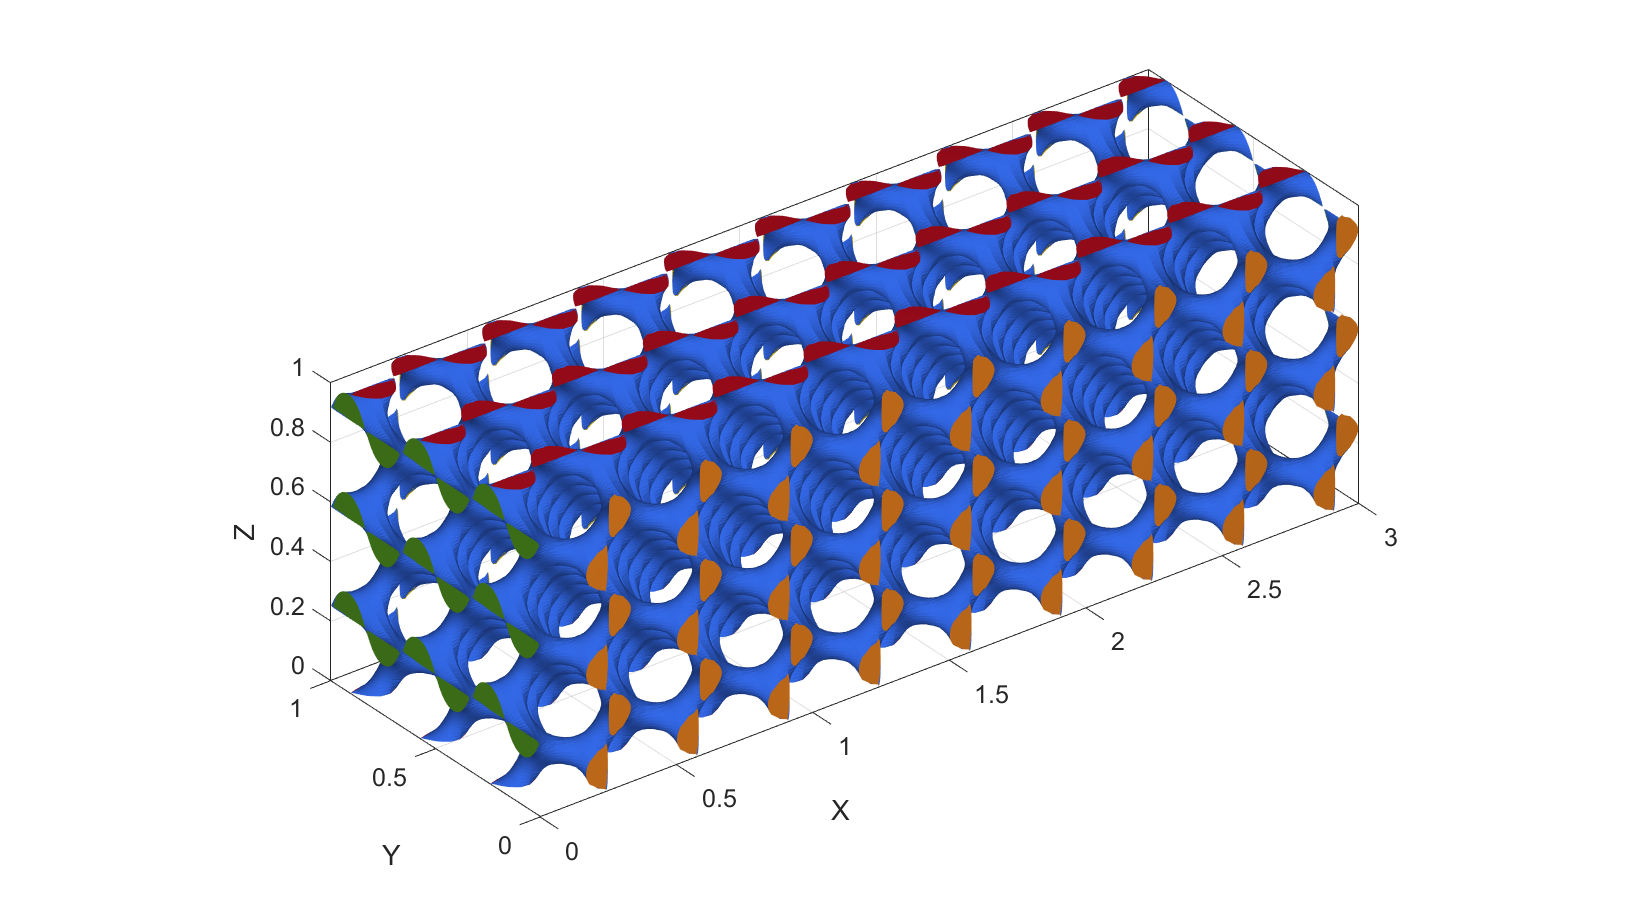

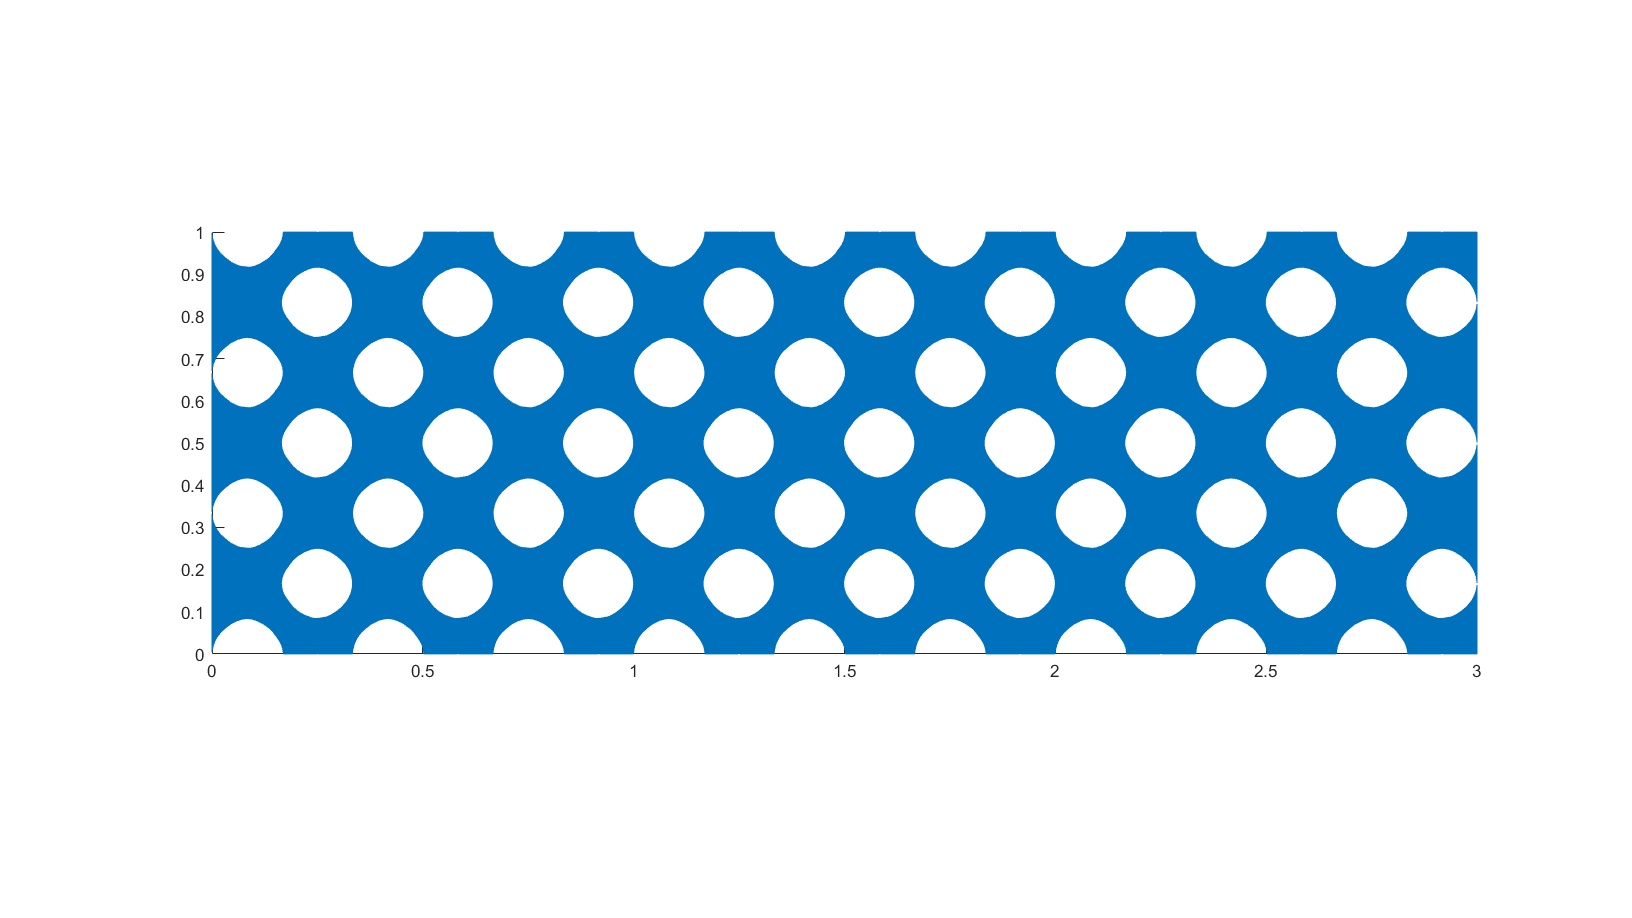

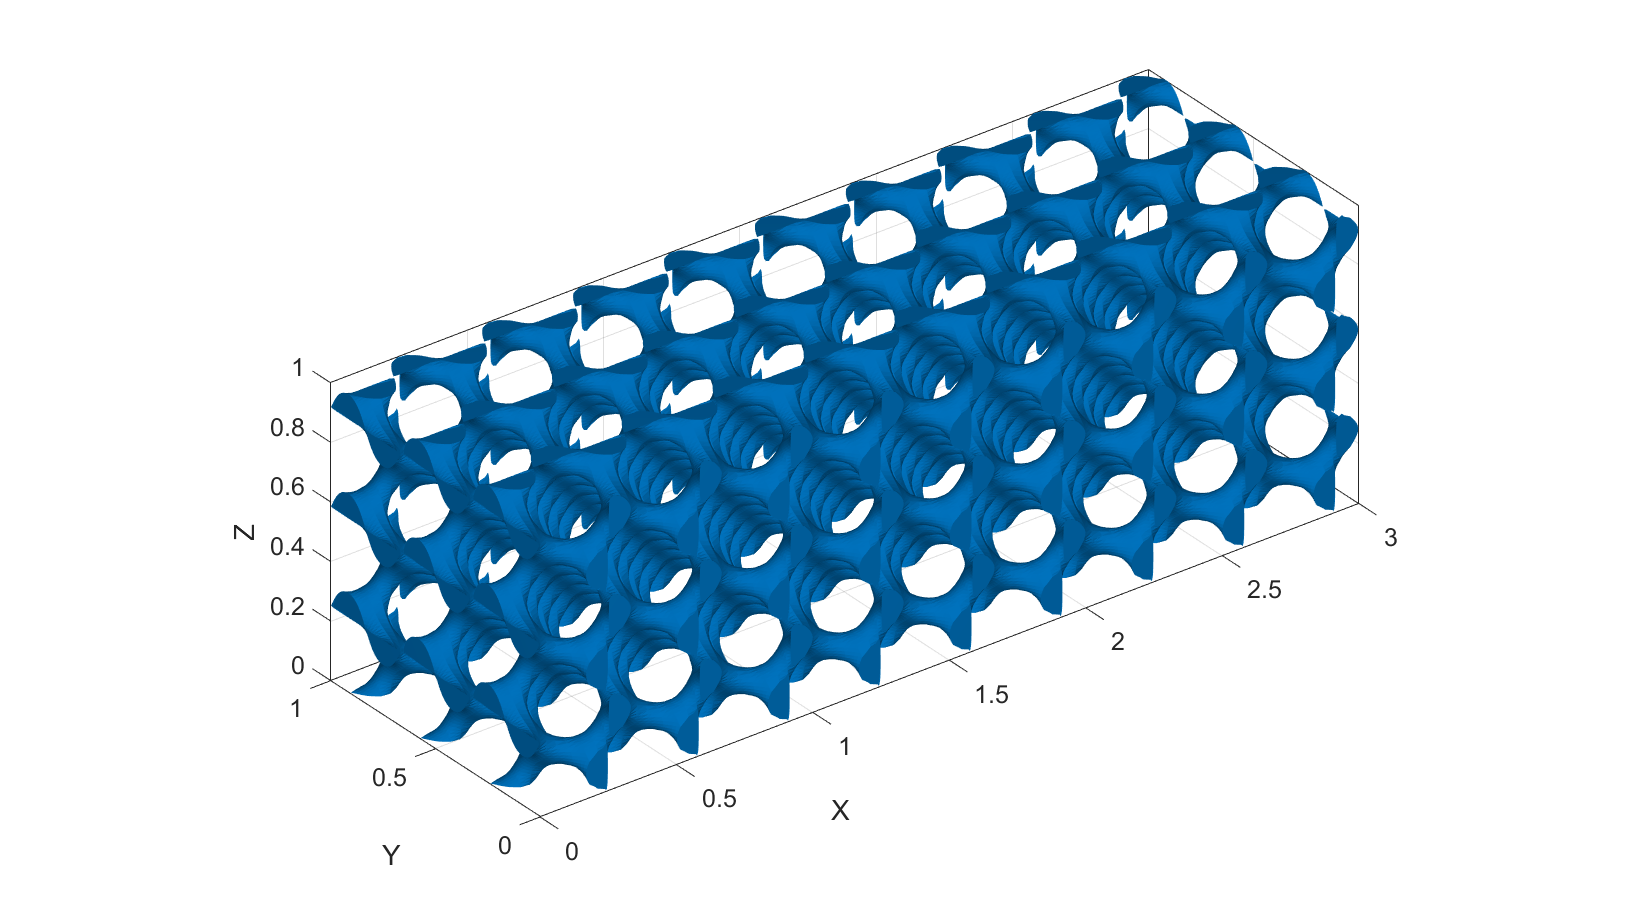

optionStruct.pointSpacing=pointSpacing;
[F,V]=ggremesh(f,v,optionStruct);
C=zeros(size(F,1),1);

% Visualizing geometry
cFigure; hold on;

if figureTitles
    title('Geogram remeshed','FontSize',fontSize);
end


gpatch(F,V,'w','k',1);
axisGeom(gca,fontSize);
camlight headlight;
drawnow;

## Tetrahedral meshing using tetgen (see also `runTetGen`)

Create tetgen input structure

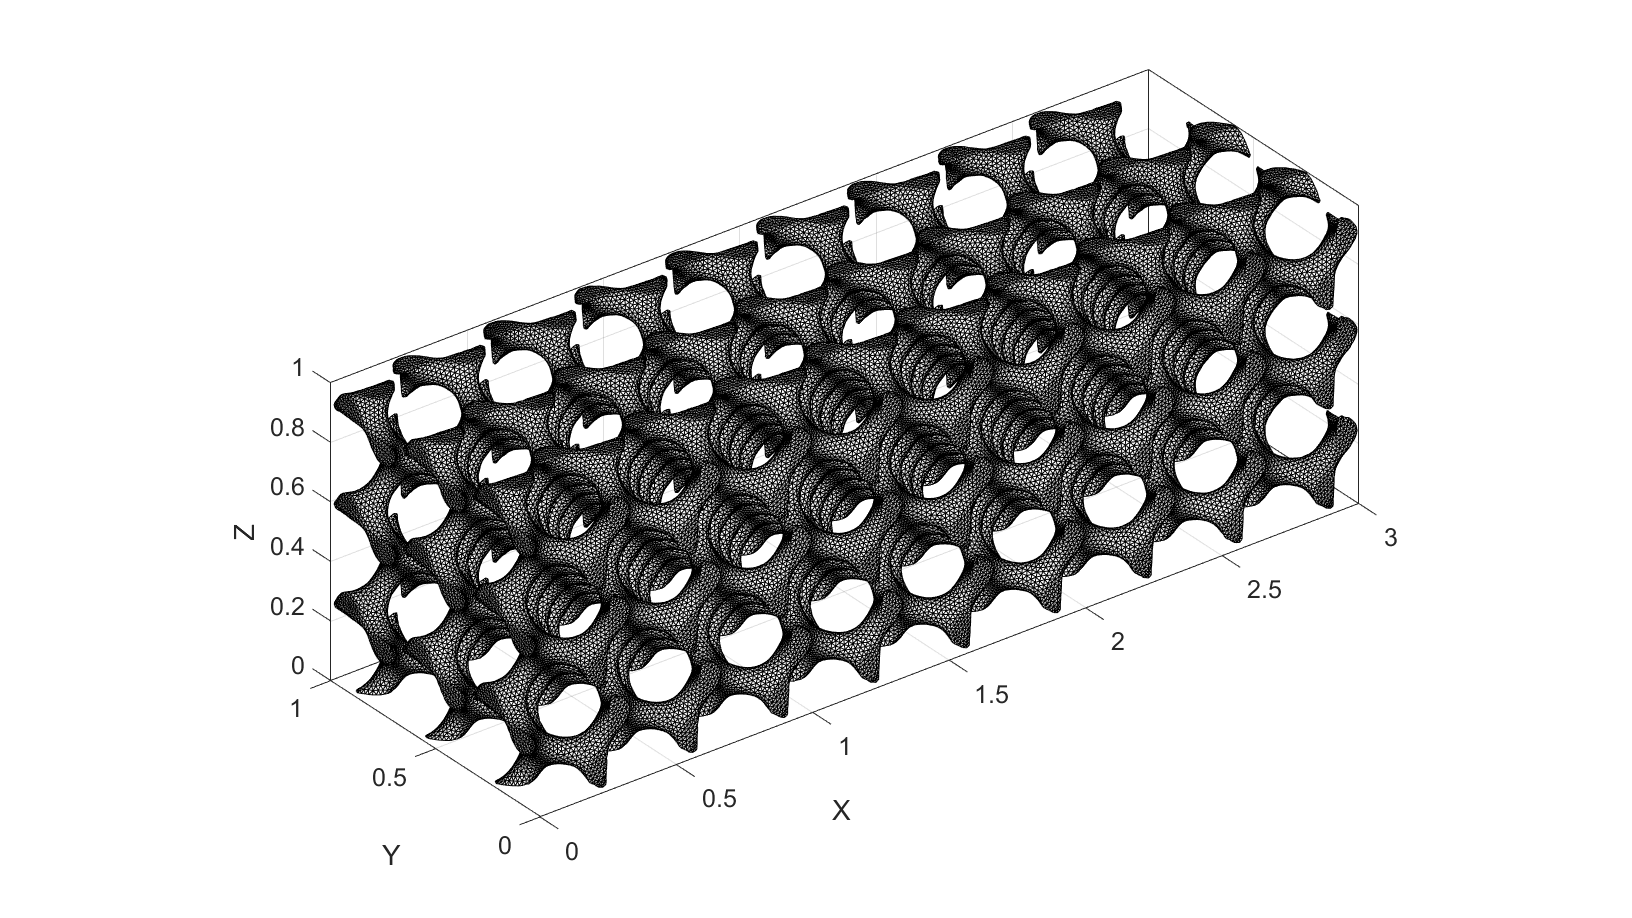

%%%%%%%%%%%%%%%% while loop start
maxIterations = 20;
iterationCount = 0;

while iterationCount < maxIterations

    if coarseMesh
        optionStruct.pointSpacing = 0.04;
    end

    [F,V]=ggremesh(f,v,optionStruct);
    C=zeros(size(F,1),1);


    inputStruct.stringOpt='-pq1.2AaY';
    inputStruct.Faces=F;
    inputStruct.Nodes=V;
    inputStruct.holePoints=[];
    inputStruct.faceBoundaryMarker=C; %Face boundary markers
    inputStruct.regionPoints=getInnerPoint(F,V); %region points
    inputStruct.regionA=2*tetVolMeanEst(F,V);
    inputStruct.minRegionMarker=2; %Minimum region marker

    [meshOutput]=runTetGen(inputStruct); %Run tetGen

    numElements = size(meshOutput.elements, 1);

    fprintf("%i Elements generated\n",numElements);

    if coarseMesh
        break;
    elseif numElements > 1000000 % increase pointSpacing
        optionStruct.pointSpacing = optionStruct.pointSpacing + 0.01
    elseif numElements > 500000
        optionStruct.pointSpacing = optionStruct.pointSpacing + 0.005
    elseif numElements > 300000
        optionStruct.pointSpacing = optionStruct.pointSpacing + 0.003
    elseif numElements > 250000
        optionStruct.pointSpacing = optionStruct.pointSpacing + 0.001
    elseif numElements < 200000 % reduce pointSpacing
        optionStruct.pointSpacing = optionStruct.pointSpacing - 0.001
    else
        break;
    end

    iterationCount = iterationCount + 1;
end

if iterationCount == maxIterations
    warning('Maximum iterations reached without achieving desired element count.');
end


% Access model element and patch data
Fb=meshOutput.facesBoundary;
Cb=meshOutput.boundaryMarker;
V=meshOutput.nodes;
CE=meshOutput.elementMaterialID;
E=meshOutput.elements;

V_mesh = sum(tetVol(E,V,0)); % Mesh volume (through sum of tet elements volume)
Infill_percentage = (V_mesh / 3) * 100; % assuming volume of 3

## Visualizing mesh using `meshView`, see also `anim8`

meshView(meshOutput);

## Defining node labels

C_vertex=zeros(size(V,1),1);

% logic1=V(:,3)>(Dim(1,4)-tolDir);
logic1=V(:,1)>(3-tolDir);
logic2=V(:,1)<tolDir;

C_vertex(logic1)=max(C_vertex(:))+1;
C_vertex(logic2)=max(C_vertex(:))+1;

logic3=V(:,3)>(1-tolDir)&V(:,1)>1.5;
logic4=V(:,3)<tolDir&V(:,1)>1.5;

C_vertex(logic3)=max(C_vertex(:))+1;
C_vertex(logic4)=max(C_vertex(:))+1;

 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
--- TETGEN Tetrahedral meshing --- 10-Feb-2025 13:01:49
 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
--- Writing SMESH file --- 10-Feb-2025 13:01:49
----> Adding node field
----> Adding facet field
----> Adding holes specification
----> Adding region specification
--- Done --- 10-Feb-2025 13:01:49
--- Running TetGen to mesh input boundary--- 10-Feb-2025 13:01:49
Opening C:\Users\rusco\OneDrive - University of Warwick\Admin\Archives\Documents\GitHub\LatticeWorks\GIBBON\data\temp\temp.smesh. 
Delaunizing vertices... 
Delaunay seconds:  0.064 
Creating surface mesh ... 
Surface mesh seconds:  0.017 
Recovering boundaries... 
Boundary recovery seconds:  0.076 
Removing exterior tetrahedra ... 
Spreading region attributes. 
Exterior tets removal seconds:  0.038 
Recovering Delaunayness... 
Delaunay recovery seconds:  0.018 
Refining mesh... 
Refinement seconds:  0.075 
Optimizing mesh... 
Optimization seconds:  0.014 
 
Writing C:\Users\rus

56396 Elements generated


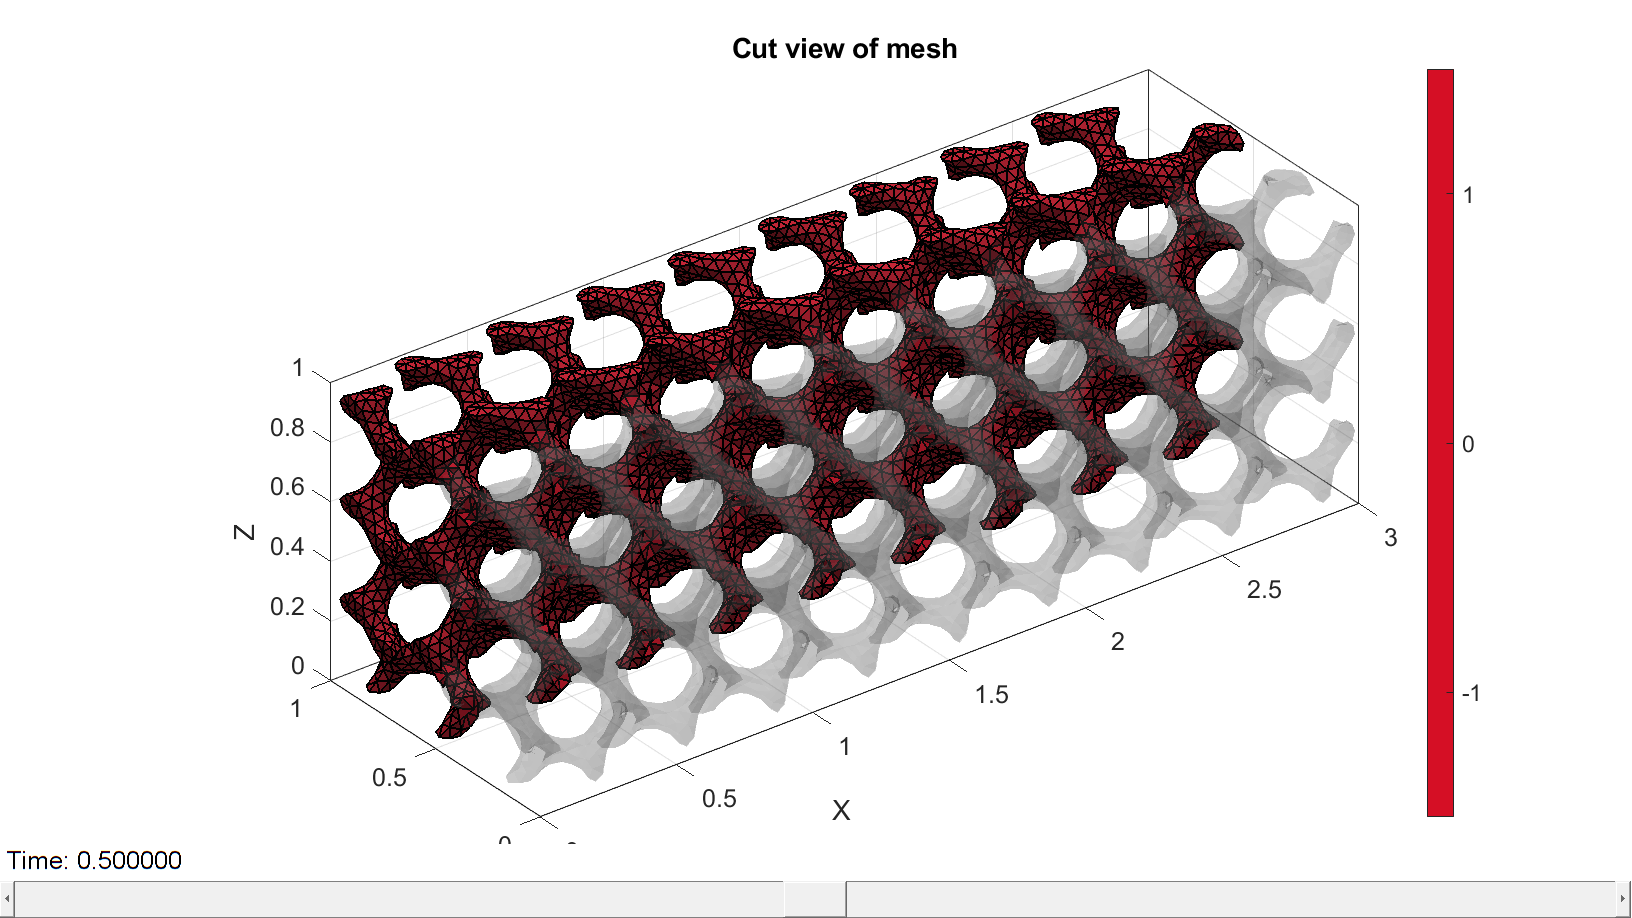


logic5 = (V(:,2) > (1 - tolDir)) & (V(:,1) > 1.5);  
logic6 = (V(:,2) < tolDir) & (V(:,1) > 1.5);


C_vertex(logic5) = max(C_vertex(:)) + 1;
C_vertex(logic6) = max(C_vertex(:)) + 1;

% Visualizing vertex/node labels
hf=cFigure;

if figureTitles
    title('Boundary Nodes','FontSize',fontSize);
end

xlabel('X','FontSize',fontSize); ylabel('Y','FontSize',fontSize); zlabel('Z','FontSize',fontSize);
hold on;

gpatch(Fb,V,'w','none',1);
scatterV(V,10,C_vertex,'filled');

axisGeom(gca,fontSize);
colormap gjet; icolorbar;
camlight headlight;
drawnow;

% red load
% yellow boundary condition

## Defining the boundary conditions

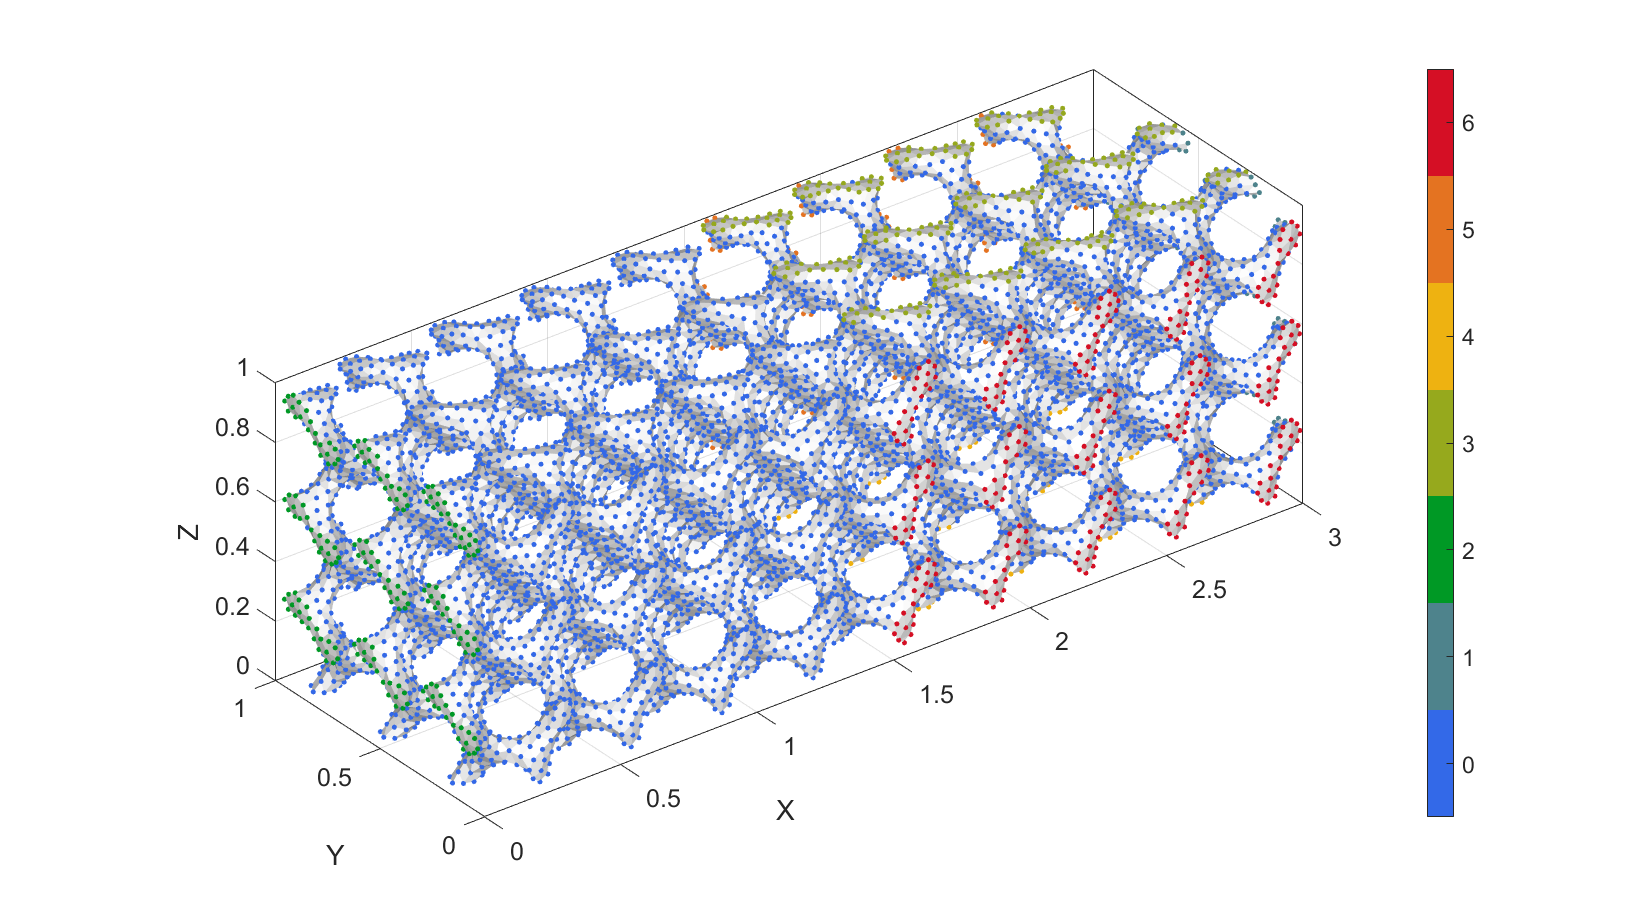

bcEncastreList=find(C_vertex==1); % Encastre vertices
bcLoadList=find(C_vertex==2); % Load vertices
bcTrackZ1=find(C_vertex==3);
bcTrackZ0=find(C_vertex==4);
bcTrackY0=find(C_vertex==5);
bcTrackY1=find(C_vertex==6);

bcTrackZ = union(bcTrackZ1, bcTrackZ0);
bcTrackY = union(bcTrackY1, bcTrackY0);

% Visualizing boundary conditions. 
% Markers plotted on the semi-transparent model denote the nodes in the
% various boundary condition lists.

hl=cFigure;
if figureTitles
    title('Boundary conditions','FontSize',fontSize);
end
xlabel('X','FontSize',fontSize); ylabel('Y','FontSize',fontSize); zlabel('Z','FontSize',fontSize);

hold on;
gpatch(Fb,V,'kw','none',0.5);

hl(1)=plotV(V(bcEncastreList,:),'r*','MarkerSize',markerSize/3);
hl(2)=plotV(V(bcLoadList,:),'k.','MarkerSize',markerSize);
hl(3)=plotV(V(bcTrackZ,:),'b.','MarkerSize',markerSize/3);
hl(4)=plotV(V(bcTrackY,:),'c.','MarkerSize',markerSize/3);
legend(hl,{'BC Load','BC Encastre','BC Track Z','BC Track Y'});

axisGeom(gca,fontSize);
camlight headlight;
drawnow;

## Save all Figures

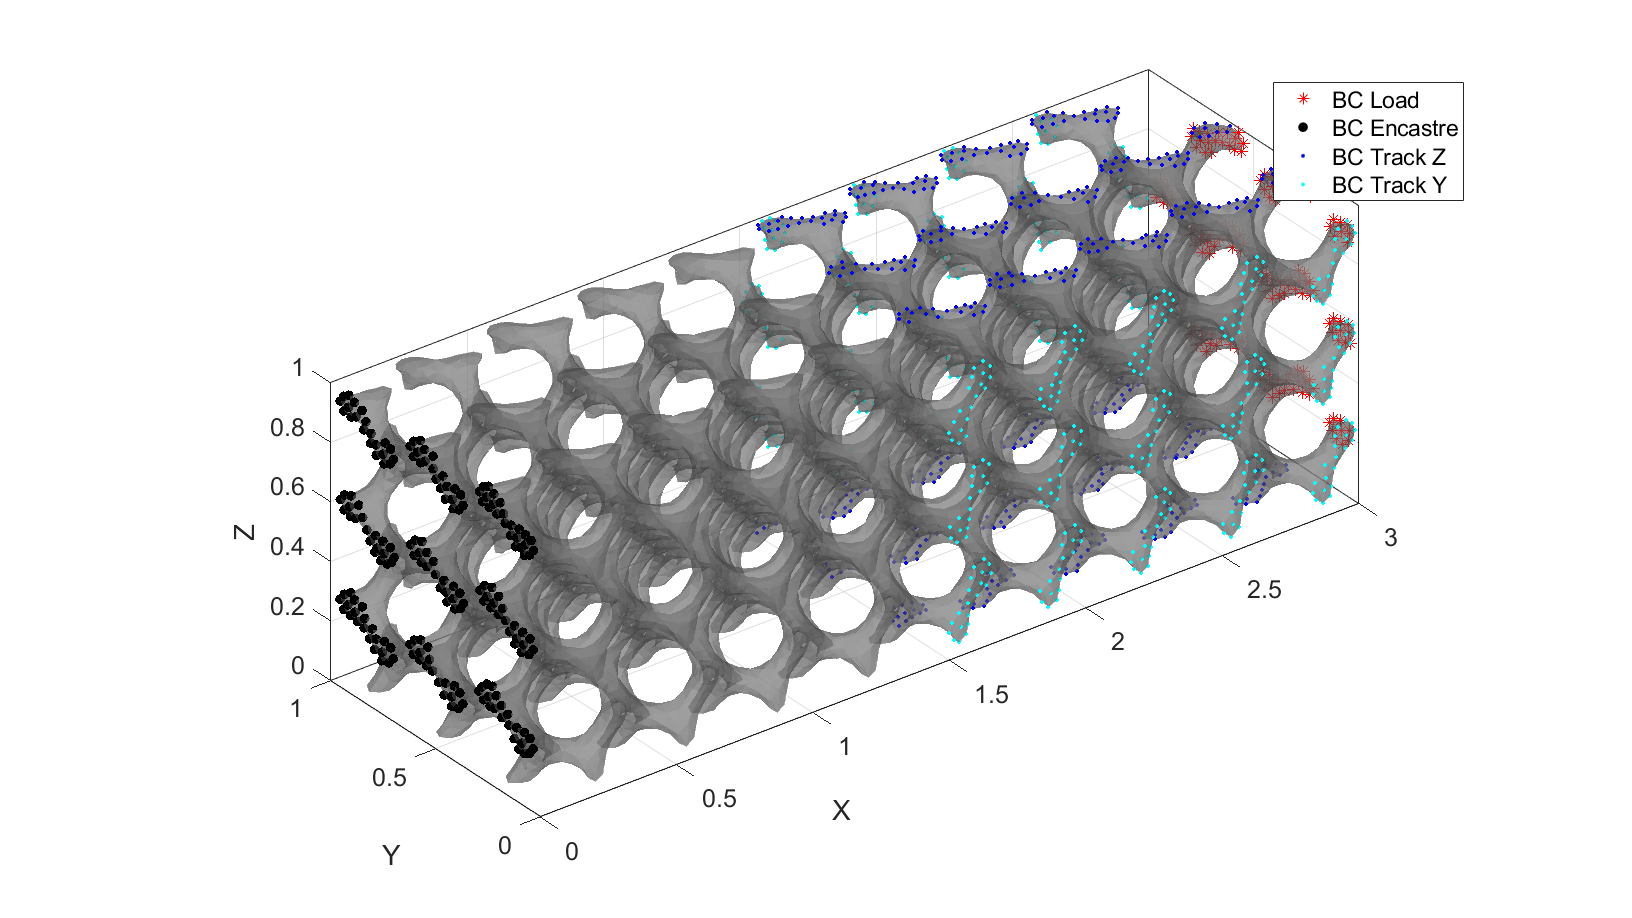

figsavePath = fullfile(savePath, 'Figures')
figHandles = findobj('Type', 'figure');

mkdir(figsavePath);

% Iterate over each figure
for i = 1:length(figHandles)
    % Get the current figure handle
    figHandle = figHandles(i);
    
    % Generate a unique filename based on the figure number
    figName = sprintf('Figure_%d', figHandle.Number);
    
    % Save the figure as a .fig file
    savefig(figHandle, fullfile(figsavePath, [figName, '.fig']));
    
    % Save the figure as a .png file
    saveas(figHandle, fullfile(figsavePath, [figName, '.png']));
    
    % Close the figure
    close(figHandle);

end

nFigures = length(figHandles);

## Defining the abaqus input structure

See also `abaqusStructTemplate` and `abaqusStruct2inp` and the abaqus user manual.

%%--> Heading
abaqus_spec.Heading.COMMENT{1}='Job name: ABAQUS inp file creation demo';
abaqus_spec.Heading.COMMENT{2}='Generated by: GIBBON';

%%--> Preprint
abaqus_spec.Preprint.ATTR.echo='NO';
abaqus_spec.Preprint.ATTR.model='NO';
abaqus_spec.Preprint.ATTR.history='NO';
abaqus_spec.Preprint.ATTR.contact='NO';
abaqus_spec.Preprint.ATTR.contact='NO';

%--> Part

% Node
nodeIds=(1:1:size(V,1))';
abaqus_spec.Part.COMMENT='This section defines the part geometry in terms of nodes and elements';
abaqus_spec.Part.ATTR.name='Lattice';
abaqus_spec.Part.Node={nodeIds,V};

% Element
elementIds=(1:1:size(E,1));
abaqus_spec.Part.Element{1}.ATTR.type='C3D4';%'C3D8R';
abaqus_spec.Part.Element{1}.VAL={elementIds(:),E};

figsavePath = 'C:\Users\rusco\AppData\Local\Temp\TechnicalReport\LatticeProperties\1_Lattice_Density\Figures'


% Element sets
abaqus_spec.Part.Elset{1}.ATTR.elset='Set-1';
abaqus_spec.Part.Elset{1}.VAL=elementIds;

% Sections
abaqus_spec.Part.Solid_section.ATTR.elset='Set-1';
abaqus_spec.Part.Solid_section.ATTR.material='Elastic';

if ~linear
    % *on, name=Ori-1, system=RECTANGULAR
    % Ori-1-DiscOrient
    % 2, 90.
    abaqus_spec.Orientation.ATTR.name='Ori-1';
    abaqus_spec.Orientation.ATTR.system='RECTANGULAR';
    abaqus_spec.Orientation.VAL=['Ori-1-DiscOrient' newline vec2strIntDouble([2 90],'%i')];
end

%%--> Assembly
abaqus_spec.Assembly.ATTR.name='Assembly-1';
abaqus_spec.Assembly.Instance.ATTR.name='Lattice-assembly';
abaqus_spec.Assembly.Instance.ATTR.part='Lattice';

abaqus_spec.Assembly.Nset{1}.ATTR.nset='Set-1';
abaqus_spec.Assembly.Nset{1}.ATTR.instance='Lattice-assembly';
abaqus_spec.Assembly.Nset{1}.VAL=bcEncastreList(:)';

abaqus_spec.Assembly.Nset{2}.ATTR.nset='Set-2';
abaqus_spec.Assembly.Nset{2}.ATTR.instance='Lattice-assembly';
abaqus_spec.Assembly.Nset{2}.VAL=bcLoadList(:)';

abaqus_spec.Assembly.Nset{3}.ATTR.nset='all';
abaqus_spec.Assembly.Nset{3}.ATTR.instance='Lattice-assembly';
abaqus_spec.Assembly.Nset{3}.VAL=1:1:size(V,1);

%%--> Material
if linear
    abaqus_spec.Material.ATTR.name='Elastic';
    abaqus_spec.Material.Elastic=[E_youngs v_poisson];
else % Material, anisotropic
    abaqus_spec.Material.ATTR.name='Elastic';
    % abaqus_spec.Material.Elastic = 'type = ENGINEERING CONSTANTS\n2580, 2580, 2060, 0.35, 0.3, 0.3, 955.56, 992.31, 992.31';

    E1   = 2580; E2   = 2580; E3   = 2060; % Young's moduli
    nu12 = 0.35; nu13 = 0.3; nu23 = 0.3; % Poisson's ratios
    G12  = 955.56; G13  = 992.31; G23  = 992.31; % Shear moduli
    abaqus_spec.Material.Elastic = sprintf('type = ENGINEERING CONSTANTS\n%g, %g, %g, %g, %g, %g, %g, %g, %g', E1, E2, E3, nu12, nu13, nu23, G12, G13, G23);

    % defaultOriString = sprintf('1., 0., 0., 0., 1., 0.\n3, 0.');
    % % Set up the Abaqus orientation in your GIBBON structure:
    % abaqus_spec.Orientation.ATTR.name = 'Ori-1';
    % % abaqus_spec.Orientation.ATTR.system = 'RECTANGULAR';
    % abaqus_spec.Orientation.VAL = defaultOriString;
end

%%--> Step
abaqus_spec.Step.ATTR.name='Step-1';
abaqus_spec.Step.ATTR.nlgeom='YES';
abaqus_spec.Step.Static=[0.01 1 1e-5 0.1];

%--> Boundary
abaqus_spec.Step.Boundary{1}.VAL={'Set-1', 'ENCASTRE'};
% abaqus_spec.Step.Boundary{1}.VAL={'Set-1',[1,1]};
% abaqus_spec.Step.Boundary{2}.VAL={'Set-1',[4,6]};
abaqus_spec.Step.Boundary{2}.VAL={'Set-2',[1,1],displacementMagnitude};

%--> Output
%Nodal coordinates
abaqus_spec.Step.Node_print{1}.ATTR.nset='all';
abaqus_spec.Step.Node_print{1}.ATTR.frequency = 1;
abaqus_spec.Step.Node_print{1}.VAL='COORD';

abaqus_spec.Step.El_print{1}.VAL='S';
abaqus_spec.Step.El_print{2}.VAL='E';

## writing INP file

if updateSim

abaqusStruct2inp(abaqus_spec,abaqusInpFileName);

## Run the job using Abaqus

lockFileName=fullfile(savePath,[abaqusInpFileNamePart,'.lck']);

if exist(lockFileName,'file')
    warning('Lockfile found and deleted')
    delete(lockFileName);
end

oldPath=pwd; %Get current working directory
cd(savePath); %Set new working directory to match save path

abaqusPath='C:\SIMULIA\Commands\abaqus.bat';%'/usr/bin/abaqus'; %Abaqus excute command or path
[runFlag, cmdOut] = system([abaqusPath,' inp=',abaqusInpFileName,' job=',abaqusInpFileNamePart,' interactive ask_delete=OFF', 'cpus=',int2str(6)]);
disp(cmdOut);

cd(oldPath); %Restore working directory
else
    fprintf('Abaqus files for [%.1g] Lattice density exist and should not be overwritten, proceeding\n', i);
end

## Import and visualize abaqus results

Importing the abaqus .dat file 

% [abaqusData]=importAbaqusDat(abaqusDATFileName);

try
    % Attempt to import the Abaqus data file.
    abaqusData = importAbaqusDat(abaqusDATFileName);
catch ME
    % If import fails, open the file for reading.
    fid = fopen(abaqusDATFileName, 'rt');
    if fid == -1
        error('Unable to open file: %s', abaqusDATFileName);
    else
        fileText = fread(fid, '*char')';
        fclose(fid);

        % Check if the error message appears in the file.
        if contains(fileText, '***ERROR: Academic Teaching license is limited to 250000 nodes.')
            warning('The file %s indicates an Academic Teaching license limitation.', abaqusDATFileName);
        % else % unkown error, open and manually check
        %     winopen(abaqusDATFileName);
        end
    end
end

## Get element data

E_effectiveStress=zeros(size(E,1),numel(abaqusData.STEP.INCREMENT)+1);
E_effectiveStrain=zeros(size(E,1),numel(abaqusData.STEP.INCREMENT)+1);
for q=1:1:numel(abaqusData.STEP.INCREMENT)
    
    for d=1:1:2        
        dataSet=abaqusData.STEP.INCREMENT(q).elementOutput(d); %Get data structure
        switch d
            case 1

Analysis initiated from SIMULIA established products
Abaqus JOB Lattice_FEA
Abaqus 2024
Abaqus License Manager checked out the following licenses:
Abaqus/Standard checked out 5 tokens from Flexnet server AbaqusLicense.soe.warwick.ac.uk.
<1105 out of 1120 licenses remain available>.
Begin Analysis Input File Processor
2/10/2025 1:02:17 PM
Run pre.exe
2/10/2025 1:02:20 PM
End Analysis Input File Processor
Begin Abaqus/Standard Analysis
2/10/2025 1:02:20 PM
Run standard.exe
2/10/2025 1:03:03 PM
End Abaqus/Standard Analysis
Begin SIM Wrap-up
2/10/2025 1:03:04 PM
Run SMASimUtility.exe
2/10/2025 1:03:04 PM
End SIM Wrap-up
Abaqus JOB Lattice_FEA COMPLETED



                % Get element data across all 1 integration points
                D11_PT=reshape(dataSet.data.S11,1,size(E,1))';
                D22_PT=reshape(dataSet.data.S22,1,size(E,1))';
                D33_PT=reshape(dataSet.data.S33,1,size(E,1))';
                D12_PT=reshape(dataSet.data.S12,1,size(E,1))';
                D13_PT=reshape(dataSet.data.S13,1,size(E,1))';
                D23_PT=reshape(dataSet.data.S23,1,size(E,1))';
            case 2
                % Get element data across all 1 integration points
                D11_PT=reshape(dataSet.data.E11,1,size(E,1))';
                D22_PT=reshape(dataSet.data.E22,1,size(E,1))';
                D33_PT=reshape(dataSet.data.E33,1,size(E,1))';
                D12_PT=reshape(dataSet.data.E12,1,size(E,1))';
                D13_PT=reshape(dataSet.data.E13,1,size(E,1))';
                D23_PT=reshape(dataSet.data.E23,1,size(E,1))';                
        end
        
        % Get mean element metrics
        D11=mean(D11_PT,2);
        D22=mean(D22_PT,2);
        D33=mean(D33_PT,2);
        D12=mean(D12_PT,2);
        D13=mean(D13_PT,2);
        D23=mean(D23_PT,2);
        
        % Calculate effective (Von Mises) metrics
        switch d
            case 1
                E_effectiveStress(:,q+1)=(1/sqrt(2)).*sqrt((D11-D22).^2+(D11-D33).^2+(D33-D11).^2+6*D12.^2+6*D23.^2+6*D13.^2);
            case 2
                E_effectiveStrain(:,q+1)=(1/sqrt(2)).*sqrt((D11-D22).^2+(D11-D33).^2+(D33-D11).^2+6*D12.^2+6*D23.^2+6*D13.^2);
        end
    end
end

Plotting the simulated results using `anim8` to visualize and animate deformations

%Getting final nodal coordinates
V_def=[abaqusData.STEP(1).INCREMENT(end).nodeOutput(1).data.COOR1...
    abaqusData.STEP(1).INCREMENT(end).nodeOutput(1).data.COOR2...
    abaqusData.STEP(1).INCREMENT(end).nodeOutput(1).data.COOR3];
U=V_def-V; %Displacements

colorDataVertices=sqrt(sum(U.^2,2)); %Displacement magnitude data for coloring 

timeVec=[0 abaqusData.STEP(1).INCREMENT(:).TOTAL_TIME_COMPLETED];

% Get limits for plotting
minV=min([V;V_def],[],1); %Minima
maxV=max([V;V_def],[],1); %Maxima

% Create basic view and store graphics handle to initiate animation
hf=cFigure; %Open figure
gtitle([abaqusInpFileNamePart,': Displacement data']);
hp=gpatch(Fb,V_def,colorDataVertices,'none',1); %Add graphics object to animate
gpatch(Fb,V,0.5*ones(1,3),'k',0.25); %A static graphics object
axisGeom(gca,fontSize);
colormap(gjet(250)); colorbar;
caxis([0 max(colorDataVertices)]);
axis([minV(1) maxV(1) minV(2) maxV(2) minV(3) maxV(3)]); %Set axis limits statically
view(130,25); %Set view direction
camlight headlight;

% Set up animation features
animStruct.Time=timeVec; %The time vector
for qt=1:1:numel(timeVec) %Loop over time increments    
    if qt>1
        V_def=[abaqusData.STEP(1).INCREMENT(qt-1).nodeOutput.data.COOR1...
            abaqusData.STEP(1).INCREMENT(qt-1).nodeOutput.data.COOR2...
            abaqusData.STEP(1).INCREMENT(qt-1).nodeOutput.data.COOR3];
    else
        V_def=V;
    end    
    U=V_def-V; %Displacements
    colorDataVertices=sqrt(sum(U(:,3).^2,2)); %New color data
   
    %Set entries in animation structure
    animStruct.Handles{qt}=[hp hp]; %Handles of objects to animate
    animStruct.Props{qt}={'Vertices','CData'}; %Properties of objects to animate
    animStruct.Set{qt}={V_def,colorDataVertices}; %Property values for to set in order to animate
end
anim8(hf,animStruct); %Initiate animation feature
drawnow;

Plotting the simulated results using `anim8` to visualize and animate deformations

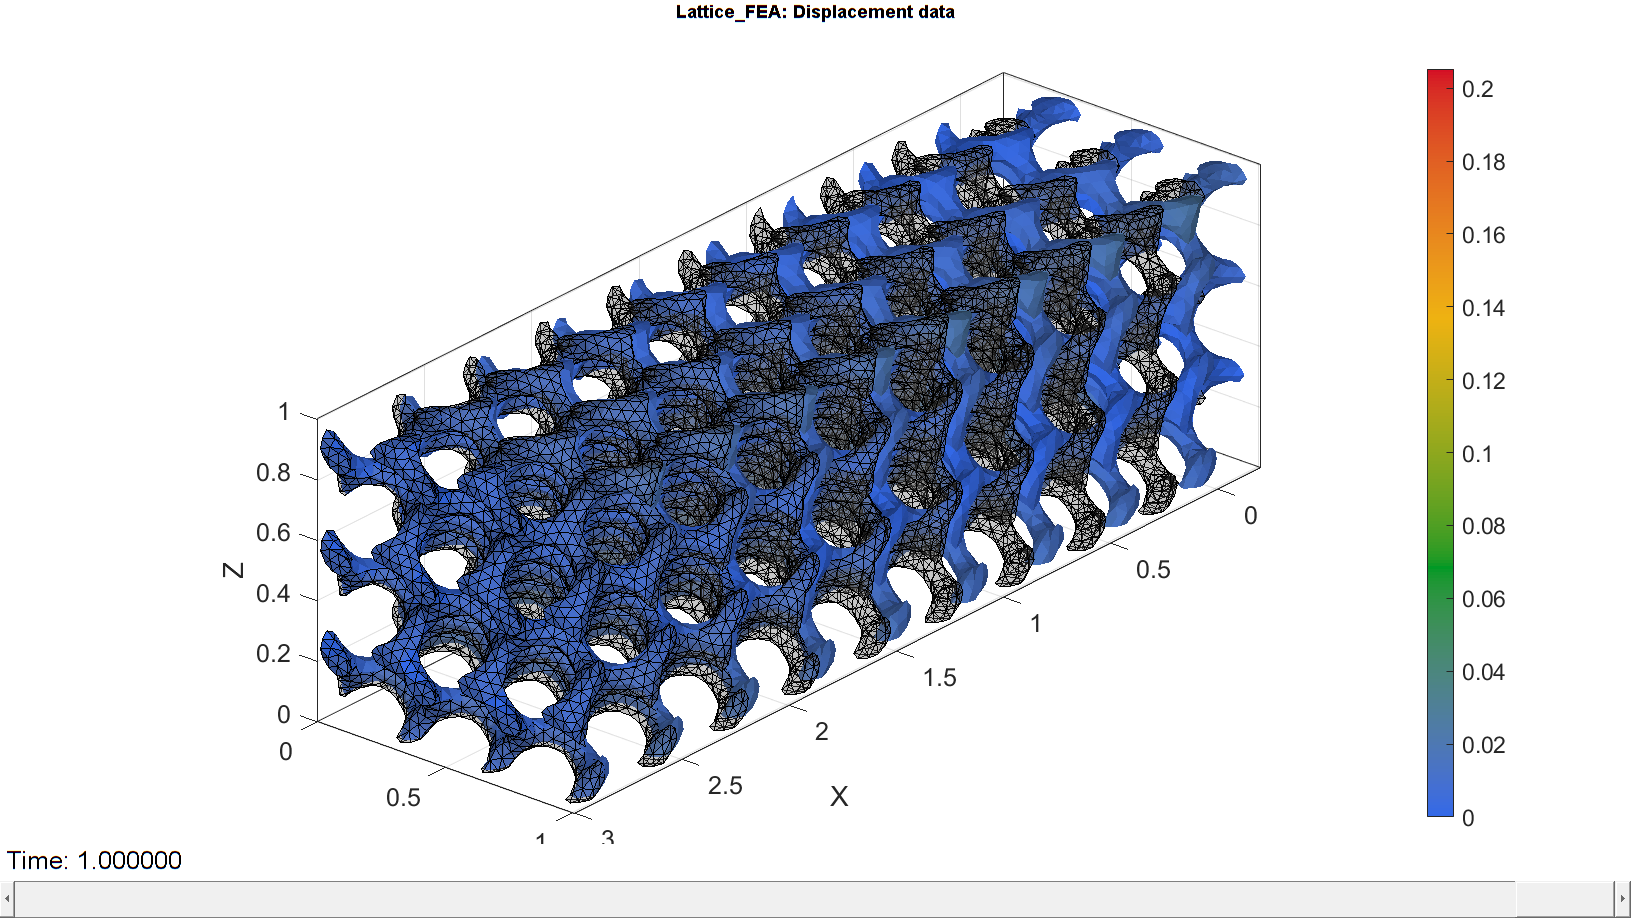

%Getting final nodal coordinates
V_def=[abaqusData.STEP(1).INCREMENT(end).nodeOutput.data.COOR1...
    abaqusData.STEP(1).INCREMENT(end).nodeOutput.data.COOR2...
    abaqusData.STEP(1).INCREMENT(end).nodeOutput.data.COOR3];
U=V_def-V; %Displacements

[FE,C_FE_effectiveStress]=element2patch(E,E_effectiveStress(:,end),'tet4');
[indBoundary]=tesBoundary(FE,V);
FEb=FE(indBoundary,:);
colorDataFaces=C_FE_effectiveStress(indBoundary); 

timeVec=[0 abaqusData.STEP(1).INCREMENT(:).TOTAL_TIME_COMPLETED];

% Get limits for plotting
minV=min([V;V_def],[],1); %Minima
maxV=max([V;V_def],[],1); %Maxima

% Create basic view and store graphics handle to initiate animation
hf=cFigure; %Open figure
gtitle([abaqusInpFileNamePart,': Effective stress (Von Mises)']);
hp=gpatch(FEb,V_def,colorDataFaces,'none',1); %Add graphics object to animate
gpatch(FEb,V,0.5*ones(1,3),'k',0.25); %A static graphics object
axisGeom(gca,fontSize);
colormap(gjet(250)); colorbar;
caxis([0 max(E_effectiveStress(:))]);
axis([minV(1) maxV(1) minV(2) maxV(2) minV(3) maxV(3)]); %Set axis limits statically
view(130,25); %Set view direction
camlight headlight;

% Set up animation features
animStruct.Time=timeVec; %The time vector
for qt=1:1:numel(timeVec) %Loop over time increments    
    if qt>1
        V_def=[abaqusData.STEP(1).INCREMENT(qt-1).nodeOutput.data.COOR1...
            abaqusData.STEP(1).INCREMENT(qt-1).nodeOutput.data.COOR2...
            abaqusData.STEP(1).INCREMENT(qt-1).nodeOutput.data.COOR3];
    else

        V_def=V;
    end    
    U=V_def-V; %Displacements
    
    [~,C_FE_effectiveStress]=element2patch(E,E_effectiveStress(:,qt),'tet4');
    colorDataFaces=C_FE_effectiveStress(indBoundary); %New color data
   
    %Set entries in animation structure
    animStruct.Handles{qt}=[hp hp]; %Handles of objects to animate
    animStruct.Props{qt}={'Vertices','CData'}; %Properties of objects to animate
    animStruct.Set{qt}={V_def,colorDataFaces}; %Property values for to set in order to animate
end
anim8(hf,animStruct); %Initiate animation feature
drawnow;

% Z displacement of tracked top and bottom
U_z = U(bcTrackZ1,3);
U_z_mean = mean(U(bcTrackZ1,3)) - mean(U(bcTrackZ0,3));
U_z_max = min(U(bcTrackZ0,2)) - max(U(bcTrackZ1,2));
U_z_test = max(U(bcTrackZ,2)) - min(U(bcTrackZ,2))
strain_z = U_z_mean / 1;
strain_x = ((-displacementMagnitude + 3) - 3)/ 3; % = deformed length / initial length

poisson_xz = -(U_z_mean/z_length) / strain_x; % note that since strain_y = U_y_mean / 1 we can conclude for this case strain_y = U_y_mean
poisson_xz_max = -(U_z_max/z_length) / strain_x;
% poisson_xz_min = -(U_z_min/z_length) / strain_x;

% Y displacement of tracked sides
U_y = U(bcTrackY1,2);
U_y_mean = mean(U(bcTrackY0,2)) - mean(U(bcTrackY1,2));
U_y_max = min(U(bcTrackY0,2)) - max(U(bcTrackY1,2));
U_y_test = min(U(bcTrackY,2)) - max(U(bcTrackY,2));

poisson_xy = -(U_y_mean/y_length) / strain_x;
poisson_xy_max = -(U_y_max/y_length) / strain_x;
% poisson_xy_min = -(U_y_min/y_length) / strain_x;

## Save New Figures

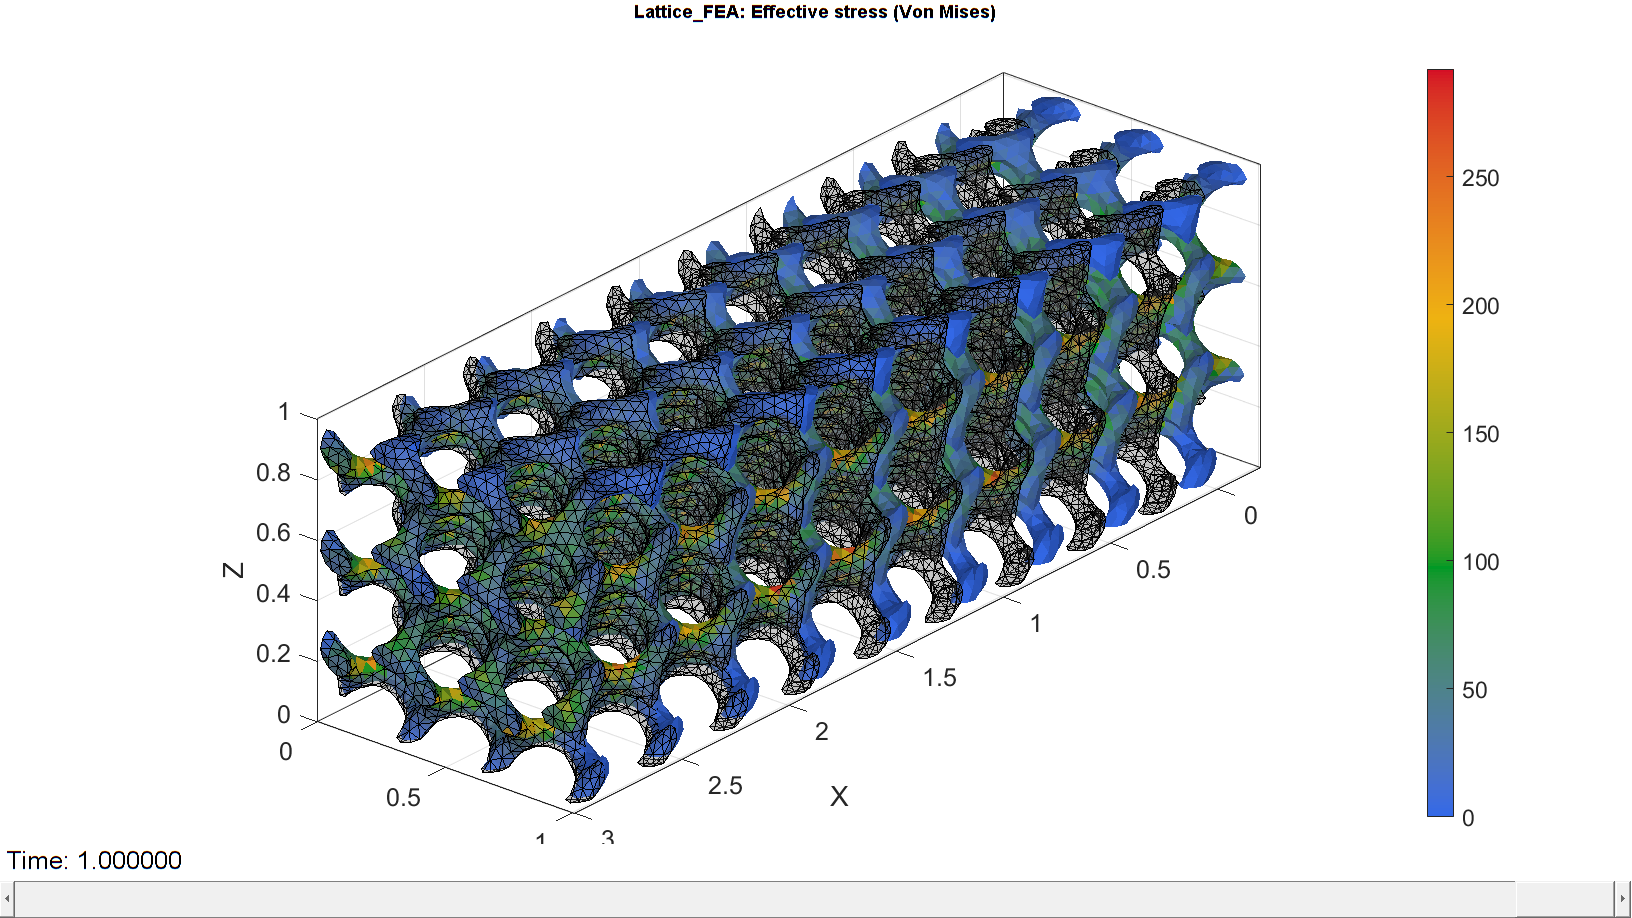

figsavePath = fullfile(savePath, 'Figures');
figHandles = findobj('Type', 'figure');

% Iterate over each figure
for i = 1:length(figHandles)
    % Get the current figure handle
    figHandle = figHandles(i);
    
    % Generate a unique filename based on the figure number
    figName = sprintf('Figure_%d', figHandle.Number + nFigures);
    
    % Save the figure as a .fig file
    savefig(figHandle, fullfile(figsavePath, [figName, '.fig']));
    
    % Save the figure as a .png file
    saveas(figHandle, fullfile(figsavePath, [figName, '.png']));
    
    % Close the figure

    close(figHandle);
end

% Define the struct with key values
resultStruct = struct();
resultStruct.timestamp = datestr(now, 'yyyy-mm-dd HH:MM:SS'); % Save execution time
resultStruct.F = F;  % Your mesh faces
resultStruct.V = V;  % Your mesh vertices
resultStruct.infill_percentage = Infill_percentage;
resultStruct.mesh_volume = V_mesh;
resultStruct.level_set = levelset;
resultStruct.poisson_xz = poisson_xz;
resultStruct.poisson_xy = poisson_xy;

saveFile = fullfile(savePath, 'simulation_results.mat'); 

% Save struct
save(saveFile, 'resultStruct');

% end

% Stop the Data Collector Set
system('logman stop CPU_Log');


U_z_test = 0.0259

catch ME
    system('logman stop CPU_Log');
    rethrow(ME);
end

The command completed successfully. 
